# Solving Orientation Tensor Equations

Equations for the second-order orientation tensor are the standard tool for modeling fiber orientation.  Here we show how to set up and solve those equation for a variety of models.  The primary function from the toolkit for this is `Adot2`.  The following sections cover a) the standard Folgar-Tucker model, b) models with anisotropic rotary diffusion, and c) slow kinetics models like RSC and RPR.

## Folgar-Tucker Model

The standard Folgar-Tucker model starts wtih Jeffery's equation and adds a term for isotropic rotary diffusion.  The tensor form of that model is Eqn. (5.33):


$$   \dot{\mathbf{A}} 
   = \mathbf{W} \cdot \mathbf{A}   - \mathbf{A} \cdot \mathbf{W}
   +  \xi ( \mathbf{D} \cdot \mathbf{A}  +\mathbf{A}  \cdot \mathbf{D}
   - 2 \mathbf{D} : \mathbb{A}) + 2 C_I \dot{\gamma} (\mathbf{I} - 3 \mathbf{A})$$


The fourth-order tensor is approximated using a closure approximation, and the natural and IBOF closures are the recommended forms.

This equation is implemented in `Adot2` and we use the built-in Matlab function `ode45` to integrate it.  The setup is just like the tensor form of Jeffery's equation, but `Adot2` has many more input parameters.

Note that the initial orientation `Avzero` is in $6 \times 1$ column vector form.  The matrix of results `Av` from `ode45` has a row for each time, and the columns correspond to the six contracted components of the orientation tensor.  

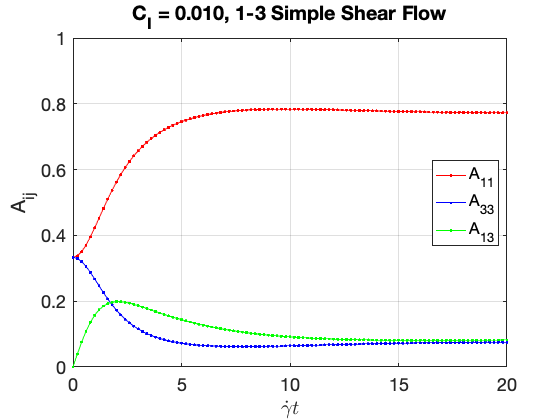

% Solve the Folgar-Tucker Model

% Problem specification
L = zeros(3,3); L(1,3) = 1;  % Velocity gradient, 1--3 simple shear flow 
xi = 1;                      % Particle shape factor
CI = 0.01;                   % Interaction coefficient
tspan = 0:0.20:20;           % Solution times
Avzero = tens2vec(eye(3)/3); % Initial condition: isotropic orientation

% Options for the fiber orientation model
closure   = 'N';    % Natural closure; use 'I' for IBOF, 'H' for hybrid
diffModel = 'F';    % Folgar-Tucker model for rotary diffusion
diffParam = CI;     % Interaction coefficient

% ODE integration options
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-9);
% Integrate the ODE
[t1, Av1] = ode45(@(t,Av) Adot2(Av, L, xi, closure, diffModel, diffParam), ...
                 tspan, Avzero, options);

% Plot the results
figure
plot(t1, Av1(:,1), 'r.-', t1, Av1(:,3), 'b.-', t1, Av1(:,5), 'g.-')

axis([0 t1(end), 0, 1])
set(gca, 'FontSize', 18)
xlabel('$\dot{\gamma} t$', 'Interpreter', 'LaTeX') 
ylabel('A_{ij}')
grid on
legend('A_{11}', 'A_{33}', 'A_{13}', 'Location', 'East')
title(sprintf('C_I = %5.3f, 1-3 Simple Shear Flow', CI))

While `ode45` will adjust its time step internally to meet the required accuracy, the solution time step should be chosen so that .  

Try changing $C_I$, the closure approximation, or $\xi$ and re-run this section.

## Anisotropic Rotary Diffusion

`Adot2` also includes most anisotropic rotary diffusion (ARD) models.  Use `diffModel` to specify the model, and `diffParam` to provide the model parameters.  Type `help Adot2` to see the options.

Here we'll use the MRD model and the parameters from Table 5.3 and the natural closure.  You can use `fitARD` to determine ARD model parameters to fit any steady-state orientation in simple shear flow.  That function is explained in `FitARDparams.mlx`.  

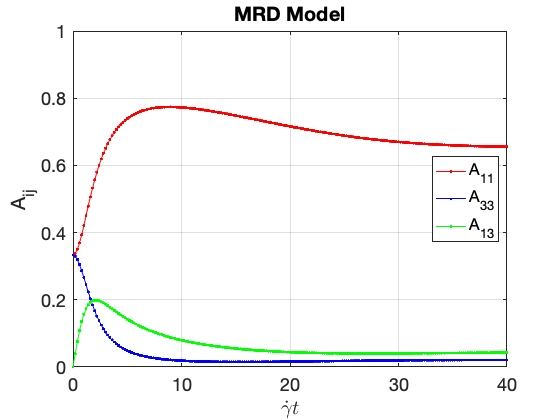

% Again relying on information from the code above . . .

% Additional options for the orientation model
diffModel = 'M';                     % MRD model
diffParam = [0.0270, 0.5, 0.0281];   % CI, D2, D3 (D1 = 1)
kinModel = 'J';   % Reset to Jeffery (standard) kinetics
kinParam = 1;     % Ignored for Jeffery kinetics

tspan2 = 0:0.20:40;  % Extend time to approach steady state

[t2, Av2] = ode45(@(t,Av) ...
            Adot2(Av, L, xi, closure, diffModel, diffParam, ...
                  kinModel, kinParam), ...
            tspan2, Avzero, options);

% Plot the results
figure
plot(t2, Av2(:,1), 'r.-', t2, Av2(:,3), 'b.-', t2, Av2(:,5), 'g.-')

axis([0 t2(end), 0, 1])
set(gca, 'FontSize', 18)
xlabel('$\dot{\gamma} t$', 'Interpreter', 'LaTeX') 
ylabel('A_{ij}')
grid on
legend('A_{11}', 'A_{33}', 'A_{13}', 'Location', 'East')
title('MRD Model')

The solution time has been extended here to allow the solution to approach steady state.  Compared to the Folgar-Tucker model, this ARD model has achieved a much lower steady-state $A_{11}$ and, at the same time, kept the steady-state value of $A_{33}$ very low.  

## Slow Kinetics Models

The same code will also solve slow kinetics models: RSC, RPR or even the SRF/slip model.  It is only necessary to pass the kinetics model and kinetics parameters to `Adot2`.  Here is the same problem, solved with the RPR model and $\kappa$ = 0.5.

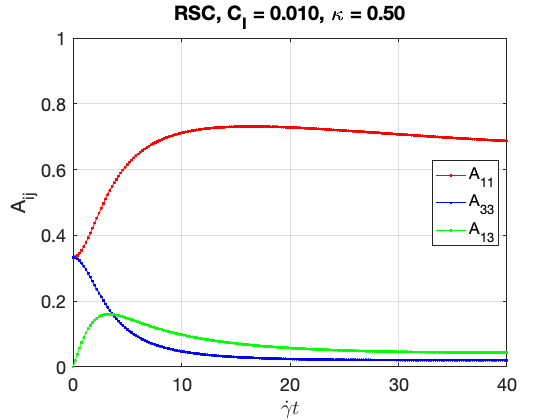

% Relying on information from the code above . . .

% Additional options for the orientation model
kinModel = 'R';     % RSC kinetics model
kinParam = 0.5;     % kappa for the RSC model

tspan3 = 0:0.2:40;  % Match times of Folgar-Tucker example

[t3, Av3] = ode45(@(t,Av) ...
            Adot2(Av, L, xi, closure, diffModel, diffParam, ...
                  kinModel, kinParam), ...
            tspan3, Avzero, options);

% Plot the results
figure
plot(t3, Av3(:,1), 'r.-', t3, Av3(:,3), 'b.-', t3, Av3(:,5), 'g.-')

axis([0 t3(end), 0, 1])
set(gca, 'FontSize', 18)
xlabel('$\dot{\gamma} t$', 'Interpreter', 'LaTeX') 
ylabel('A_{ij}')
grid on
legend('A_{11}', 'A_{33}', 'A_{13}', 'Location', 'East')
title(sprintf('RSC, C_I = %5.3f, \\kappa = %4.2f', CI, kinParam))

This plot looks similar to the Folgar-Tucker plot, but the maximum value of $\dot{\gamma} t$is twice as large here.

For injection-molded composites, $\kappa$ typically range from 0.2 to 0.03.  If you try a value in this range, increase the final value in `tspan3` before re-running this section.  

You can use `kinModel = 'P'` to get the RPR model. That model is calculated by a different route than the RSC model, but the results are identical to within numerical accuracy.  

To use slow kinetics with an ARD model, set `diffModel`, `diffParam`, `kinModel` and `kinParm` to the desired values and solve like the examples above.  